clc;
clear;
close all;

% material = ["bottle", "cable", "capsule", "carpet", "grid", "hazelnut", "leather", "metal_nut", "pill", "screw", "tile", "toothbrush", "transistor", "wood", "zipper"];

material = ["hazelnut"];
extractor = cell(length(material));

% Create structs for each element with names and multiple imds
for counter = 1:length(material)
    element(counter).name = material(counter);
    element(counter).imds = [imageDatastore(["00_data/"+material(counter)+"/train/","00_data/"+material(counter)+"/test/"], "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")];
    [element(counter).imds_train, element(counter).imds_test] = splitEachLabel(element(counter).imds, 0.7, "randomized");
end



data(counter).material = material(counter);
data(counter).imds = [imageDatastore(["00_data/"+material(counter)+"/train/","00_data/"+material(counter)+"/test/"], "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")];

for picture = 1:length(data(counter).imds)
    groundtruth = imageDatastore("00_data/"+material(counter)+"/ground_truth/", "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");

end



clc;
clear;
close all;

imdsMask = imageDatastore("00_data/bottle/ground_truth/", "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")

imdsMask =   ImageDatastore with properties:

                       Files: {
                              ' .../00_data/bottle/ground_truth/broken_large/000_mask.png';
                              ' .../00_data/bottle/ground_truth/broken_large/001_mask.png';
                              ' .../00_data/bottle/ground_truth/broken_large/002_mask.png'
                               ... and 60 more
                              }
                     Folders: {
                              ' .../frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth'
                              }
                      Labels: [broken_large; broken_large; broken_large ... and 60 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @r

imdsAllImages = imageDatastore("00_data/bottle/test/","FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")

imdsAllImages =   ImageDatastore with properties:

                       Files: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_large/000.png';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_large/001.png';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_large/002.png'
                               ... and 80 more
                              }
                     Folders: {
                              '/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test'
                              }
                      Labels: [broken_large; broken_large; broken_large ... and 80 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"



wrongImages = {};
allImages = {};
for i = 1:length(imdsAllImages.Files)
    if imdsAllImages.Labels(i)=="good"
        wrongImages{end+1,1} = string(imdsAllImages.Files(i));
    end
    allImages{end+1,1} = string(imdsAllImages.Files(i));
end

for k = 1:length(allImages)
    for j = 1:length(wrongImages)
        if k>length(allImages)
            break
        end
        if string(allImages(k,1))==string(wrongImages(j,1))
            allImages(k,:) = [];
        end
    end
end
allImages

allImages = 63×1 cell array
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/000.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/001.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/002.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/003.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/004.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/005.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/006.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/007.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/008.png"]}
    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/009.png"]}
    {["/User

     

error = {};

for size = 1:length(imdsMask.Files)
    region = regionprops(imread(imdsMask.Files{size,1}));
    region_table = struct2table(region);
    for field = 1:length(region)
        if region(field).Area > 0
            error{end+1,1} = region(field).BoundingBox;
        end
    end
    maskFilename(size, 1) = imdsMask.Files(size);
end
data = table(error);
data.maskFilename = maskFilename;
data.imageFilename = allImages

data = 63×3 table
                error                                                             maskFilename                                                                                        imageFilename                                       
    _____________________________    ______________________________________________________________________________________________________    ___________________________________________________________________________________________

    {[350.5000 284.5000 421 536]}    {'/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth/broken_large/000_mask.png'}    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_large/000.png"]}
    {[129.5000 388.5000 611 376]}    {'/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth/broken_large/001_mask.png'}    {["/Users/frederikplahl/mvtec_a


rng(0);
shuffledData = data;
shuffledIdx = randperm(height(shuffledData));
shuffledData = shuffledData(shuffledIdx,:);

% Train Test Split
cv = cvpartition(height(shuffledData),'HoldOut',0.2);
idx = cv.test;
trainingDataTbl = shuffledData(~idx,:)

trainingDataTbl = 51×3 table
                error                                                             maskFilename                                                                                         imageFilename                                        
    _____________________________    _______________________________________________________________________________________________________    ____________________________________________________________________________________________

    {[171.5000 444.5000 173 275]}    {'/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth/broken_small/019_mask.png' }    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_small/019.png" ]}
    {[182.5000 257.5000 137 383]}    {'/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth/broken_small/001_mask.png' }    {["/Users/fre

testDataTbl  = shuffledData(idx,:)

testDataTbl = 12×3 table
                error                                                             maskFilename                                                                                         imageFilename                                        
    _____________________________    _______________________________________________________________________________________________________    ____________________________________________________________________________________________

    {[156.5000 389.5000 525 281]}    {'/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth/broken_small/011_mask.png' }    {["/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_small/011.png" ]}
    {[167.5000 411.5000 107 218]}    {'/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/ground_truth/broken_small/014_mask.png' }    {["/Users/frederi


imdsTrain = imageDatastore(cellstr(trainingDataTbl{:,'imageFilename'}))

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/019.png';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/001.png';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/013.png'
                               ... and 48 more
                              }
                     Folders: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_large';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/contamination'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels:

imdsTest = imageDatastore(cellstr(testDataTbl{:,'imageFilename'}))

imdsTest =   ImageDatastore with properties:

                       Files: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/011.png';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/014.png';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/contamination/012.png'
                               ... and 9 more
                              }
                     Folders: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/contamination';
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_large'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: 


bldsTrain = boxLabelDatastore(trainingDataTbl(:,'error'))

bldsTrain =   boxLabelDatastore with properties:

    LabelData: 
               51x2 cell array
               
               {[171.5000 444.5000 173 275]}    {[error]}
               {[182.5000 257.5000 137 383]}    {[error]}
               {[454.5000 138.5000 298 202]}    {[error]}
               
                ... and 48 more rows
    ReadSize: 1


bldsTest = boxLabelDatastore(testDataTbl(:,'error'))

bldsTest =   boxLabelDatastore with properties:

    LabelData: 
               12x2 cell array
               
               {[156.5000 389.5000 525 281]}    {[error]}
               {[167.5000 411.5000 107 218]}    {[error]}
               {[254.5000 268.5000 399 394]}    {[error]}
               
                ... and 9 more rows
    ReadSize: 1



trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

imds = imdsAllImages;
blds = boxLabelDatastore(data(:,"error"));
ds = combine(imds, blds);

inputSize = [224 224 3];
preprocessedTrainingData = transform(trainingData, @(data)preprocessData(data,inputSize))

preprocessedTrainingData =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@(data)preprocessData(data,inputSize)}
               IncludeInfo: 0


numAnchors = 3;
anchorBoxes = estimateAnchorBoxes(preprocessedTrainingData,numAnchors)

anchorBoxes =    127   134
    53    46
   100    79


featureExtractionNetwork = resnet50;
featureLayer = 'activation_40_relu';
numClasses = 1;


lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

options = trainingOptions('sgdm', ...
      'MiniBatchSize', 1, ...
      'InitialLearnRate', 1e-3, ...
      'MaxEpochs', 7, ...
      'VerboseFrequency', 200, ...
      'CheckpointPath', tempdir);

detector = trainFasterRCNNObjectDetector(ds, lgraph, options, ...
        'NegativeOverlapRange',[0 0.3], ...
        'PositiveOverlapRange',[0.6 1]);

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* error

Training on single CPU.
Initializing input data normalization.
|=============================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |      Rate       |
|=============================================================================================================================================|
|       1 |           1 |       00:00:38 |       2.0726 |       10.50% |         0.15 |           26.56% |             0.69 |          0.0010 |
|       4 |         200 |       02:38:47 |       0.7348 |  

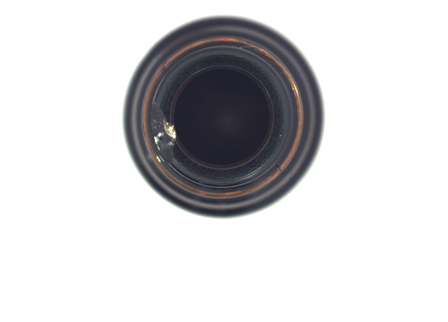

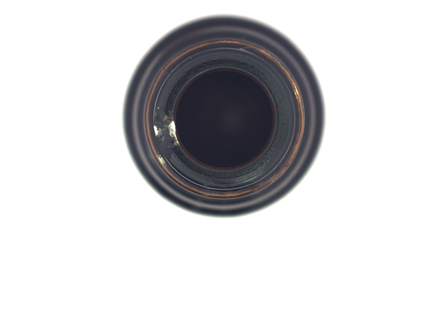

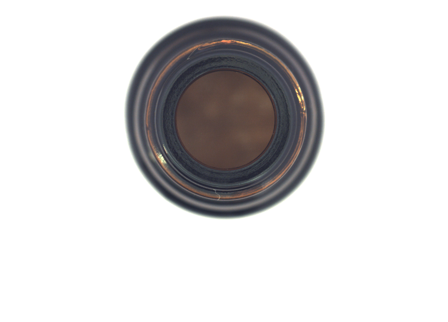

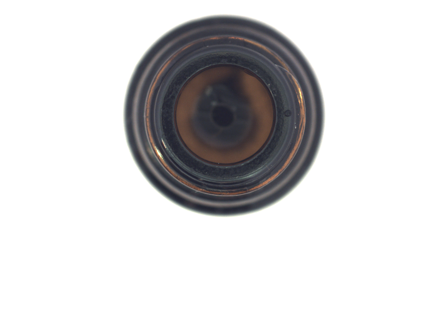

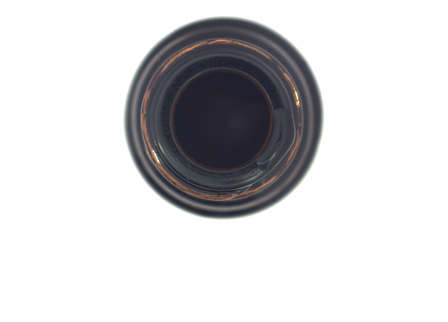

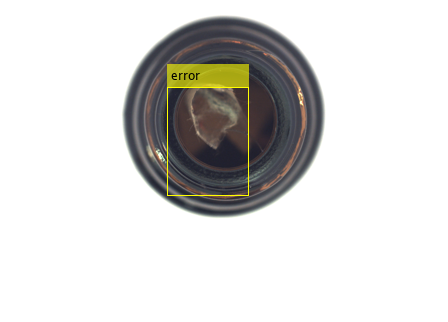

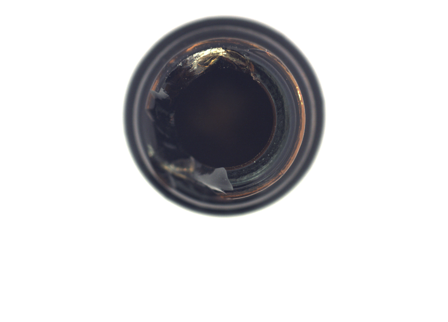

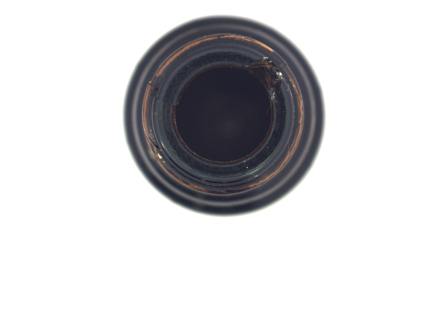

for k = 1:height(testDataTbl)
    I = imread(testDataTbl.imageFilename{k});
    I = imresize(I,inputSize(1:2));
    [bboxes,scores, label] = detect(detector,I);
    I = insertObjectAnnotation(I,'rectangle',bboxes,label);
    figure
    imshow(I)
end

clc;
clear;
close all;

data = load('vehicleTrainingData.mat')

data = struct with fields:
    vehicleTrainingData: [295×2 table]


trainingData = data.vehicleTrainingData

trainingData = 295×2 table
           imageFilename                vehicle     
    ____________________________    ________________

    {'vehicles/image_00001.jpg'}    {[126 78 20 16]}
    {'vehicles/image_00002.jpg'}    {[100 72 35 26]}
    {'vehicles/image_00003.jpg'}    {[ 62 69 26 19]}
    {'vehicles/image_00004.jpg'}    {[ 71 64 22 21]}
    {'vehicles/image_00005.jpg'}    {[147 71 25 18]}
    {'vehicles/image_00006.jpg'}    {[208 62 17 19]}
    {'vehicles/image_00007.jpg'}    {[103 71 31 27]}
    {'vehicles/image_00008.jpg'}    {[102 73 23 20]}
    {'vehicles/image_00009.jpg'}    {[ 98 69 22 18]}
    {'vehicles/image_00010.jpg'}    {[ 97 67 25 22]}
    {'vehicles/image_00011.jpg'}    {[ 94 66 33 28]}
    {'vehicles/image_00012.jpg'}    {[ 96 70 28 23]}
    {'vehicles/image_00013.jpg'}    {[ 99 71 32 23]}
    {'vehicles/image_00014.jpg'}    {[ 92 70 21 16]}
    {'vehicles/image_00015.jpg'}    {[ 92 70 21 17]}
   

trainingData(:,2:end)

ans = 295×1 table
        vehicle     
    ________________

    {[126 78 20 16]}
    {[100 72 35 26]}
    {[ 62 69 26 19]}
    {[ 71 64 22 21]}
    {[147 71 25 18]}
    {[208 62 17 19]}
    {[103 71 31 27]}
    {[102 73 23 20]}
    {[ 98 69 22 18]}
    {[ 97 67 25 22]}
    {[ 94 66 33 28]}
    {[ 96 70 28 23]}
    {[ 99 71 32 23]}
    {[ 92 70 21 16]}
    {[ 92 70 21 17]}
    {[102 69 27 19]}



%trainingData = imageDatastore(trainingData{:,'imageFilename'})
imageDatastore("/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_small/019.png")

ans =   ImageDatastore with properties:

                       Files: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/019.png'
                              }
                     Folders: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


clc;
clear;
close all;

img = imread("00_data/bottle/ground_truth/broken_large/000_mask.png");
A = {[1 1 1 1];[2 2 2 2]}

A = 2×1 cell array
    {[1 1 1 1]}
    {[2 2 2 2]}


B = {"a";"b";"c"}

B = 3×1 cell array
    {["a"]}
    {["b"]}
    {["c"]}


region = regionprops(img)

region = 255×1 struct array with fields:
    Area
    Centroid
    BoundingBox


for field = 1:length(region)
    if region(field).Area > 0
        A{end+1} = region(field).BoundingBox
        %a = region(field).BoundingBox
    end
end

A = 3×1 cell array
    {[                  1 1 1 1]}
    {[                  2 2 2 2]}
    {[350.5000 284.5000 421 536]}


t = table(A)

t = 3×1 table
                  A              
    _____________________________

    {[                  1 1 1 1]}
    {[                  2 2 2 2]}
    {[350.5000 284.5000 421 536]}




% supporting functions

function data = augmentData(data)
% Randomly flip images and bounding boxes horizontally.
tform = randomAffine2d('XReflection',true);
sz = size(data{1});
rout = affineOutputView(sz,tform);
data{1} = imwarp(data{1},tform,'OutputView',rout);

% Sanitize box data, if needed.
% data{2} = helperSanitizeBoxes(data{2}, sz);

% Warp boxes.
data{2} = bboxwarp(data{2},tform,rout);
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize box data, if needed.
% data{2} = helperSanitizeBoxes(data{2}, sz);

% Resize boxes.
data{2} = bboxresize(data{2},scale);
end